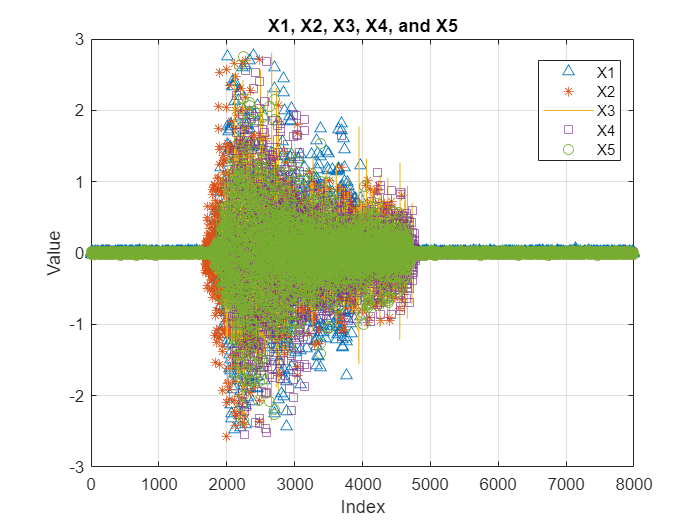

x = 1:8000;

plot(x, X1, '^', 'DisplayName', 'X1')

hold on
plot(x, X2, '*', 'DisplayName', 'X2')
plot(x, X3, '-', 'DisplayName', 'X3')
plot(x, X4, 's', 'DisplayName', 'X4')
plot(x, X5, 'o', 'DisplayName', 'X5')
hold off

title('X1, X2, X3, X4, and X5')
xlabel('Index')
ylabel('Value')
legend('Location', 'best')
grid on

plot(x, Y1, '^', 'DisplayName', 'Y1')

Error using plot
Vectors must be the same length.


hold on
plot(x, Y2, '*', 'DisplayName', 'Y2')
plot(x, Y3, '-', 'DisplayName', 'Y3')
plot(x, Y4, 's', 'DisplayName', 'Y4')
plot(x, Y5, 'o', 'DisplayName', 'Y5')
hold off

title('Y1, Y2, Y3, Y4, and Y5')
xlabel('Index')
ylabel('Y Value')
legend('Location', 'best')
grid on



num_arrays = 5;

% A matrix that will contain average distance between arrays
dif = zeros(num_arrays, num_arrays);

% this part calculate the ditances and average
for i = 1:num_arrays
    for j = i+1:num_arrays
        er = sum((eval(['X', num2str(i)]) - eval(['X', num2str(j)])).^2) / numel(eval(['X', num2str(i)]));
        dif(i, j) = er;
        disp(['average distance between X', num2str(i), ' and X', num2str(j), ' is: ', num2str(er)]);
    end
end

% A matrix that will contain average distance between arrays
dif = zeros(num_arrays, num_arrays);

% this part calculate the ditances and average
for i = 1:num_arrays
    for j = i+1:num_arrays
        er = sum((eval(['Y', num2str(i)]) - eval(['Y', num2str(j)])).^2) / numel(eval(['Y', num2str(i)]));
        dif(i, j) = er;
        disp(['average distance between Y', num2str(i), ' and Y', num2str(j), ' is: ', num2str(er)]);
    end
end

% A matrix that will contain average distance between arrays
dif = zeros(num_arrays, num_arrays);

% this part calculate the ditances and average
for i = 1:num_arrays
    er = sum((eval(['X', num2str(i)]) - eval(['Y', num2str(i)])).^2) / numel(eval(['X', num2str(i)]));
    dif(i, j) = er;
    disp(['average distance between X', num2str(i), ' and Y', num2str(i), ' is: ', num2str(er)]);
end